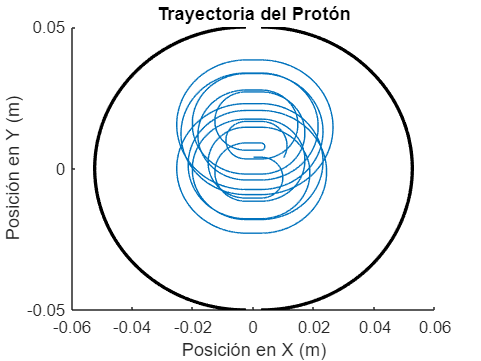

clc;close all;clear;

%Datos iniciales para la simulacion
ti=0;tf=.00000084;
h=0.0000000000001;
n=round((tf-ti)/h);

%How many iterations are stored for data analysis
%Needs to be a multiple of 10, or something
% that doesn't produce too many
%digits by dividing n, like 20 or 50. 
nStored=100;

r=zeros(n/nStored,3);
v=zeros(n/nStored,3);
normm=zeros(1,n/nStored);


%Propiedades a simular, o variables importantes
v0=[0,0,0];vf=v0;
r0=[0.00 0.0040 0];rf=r0;
r(1,:)=r0;
radius=.05;
B=[0 0 1];
SpaceBetweenDs=.005;
Voltage=5000;
%Frequency
ProtonCharge=1.602e-19;
ProtonMass=1.6726e-27;
Frequency=ProtonCharge*norm(B)/ProtonMass;
%Frequency=0.6;
t=ti;


%Something that would be pretty nice to
% implement would be only storing 1
%out of n iterations to limit ram usage. 
for i=1:n    
    [rf,vf]=Cuerpos_velVerlet(h,rf, ...
        ProtonCharge,ProtonMass,vf,Voltage, ...
        B,SpaceBetweenDs,radius,Frequency,t);

    if ~(rem(i,nStored)*i/nStored)

        r(i/nStored,:)=rf;
        v(i/nStored,:)=vf;
        
        normm(i/nStored)=norm(vf);
    end
    t=t+h;
end
% r(n/nStored,:)=rf;
% v(n/nStored,:)=vf;
% normm(n/nStored)=norm(vf);
%%
figure
hold on
plot(r(:,1),r(:,2))
theta=linspace(0,pi,100);
x=radius*sin(theta);
y=radius*cos(theta);
%This plots make a circle in the 
% trajectory plot that represent the
%cyclotron
plot(x+SpaceBetweenDs/2,y,'k','LineWidth',2)
plot(-x-SpaceBetweenDs/2,y,'k','LineWidth',2)
xlabel('Posición en X (m)')
ylabel('Posición en Y (m)')
title("Trayectoria del Protón")

hold off

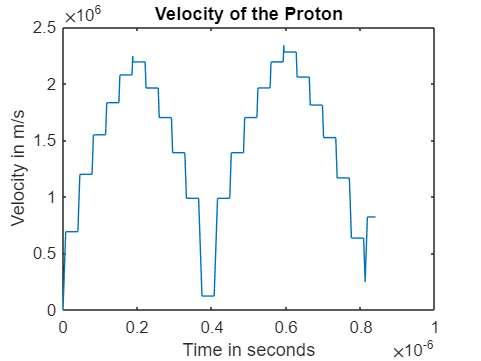

figure
plot(linspace(ti,tf,n/nStored),normm)
title("Velocity of the Proton")
xlabel("Time in seconds")
ylabel("Velocity in m/s")

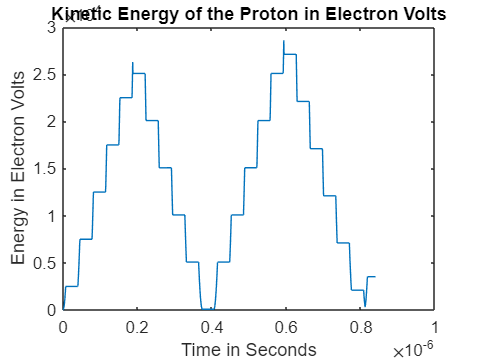

figure
plot(linspace(ti,tf,n/nStored),(1 ...
    /1.602e-19).*(1/2*(normm.^2*ProtonMass)))
title("Kinetic Energy of the Proton " + ...
    "in Electron Volts")
xlabel("Time in Seconds")
ylabel("Energy in Electron Volts")


%Esta funcion obtiene la fuerza en base a 
% la posicion y velocidad 
%de la particula

function [A]=Cyclotron_Forces(r,v,q,m,Voltage, ...
    B,SpaceBetweenDs,radius,Frequency,t)

    %Revision de si la particula esta dentro 
    % del acelerador
    space=SpaceBetweenDs;
    in=(r(1)<-space/2 && norm((r+[space/2 0 0])) ...
        <radius) || (r(1)>space/2 && ...
    norm((r-[space/2 0 0]))<radius) || ( ...
    -space/2<r(1) && r(1)<space/2 ...
    ) && abs(r(2))<radius;

    %En caso de que no este afuera, no experimenta
    % una fuerza o aceleracion 
    if in
    F=q*cross(v,B);
        if abs(r(1))<=SpaceBetweenDs/2
            Fe=[1 0 0]*q*Voltage/SpaceBetweenDs;
%             if v(1)<0
%                 Fe=-Fe;
%             end
            Fe=sign(sin(Frequency*t))*Fe;
            F=F+Fe;
        end
    A=F/m;
    else 
        A=0;
    end

    
end
%Algoritmo verlett aplicado al ciclotron
function [rf,vf]=Cuerpos_velVerlet(h,r,ProtonCharge ...
    ,ProtonMass,v,Voltage,B,SpaceBetweenDs, ...
    radius,Frequency,t)

    A=Cyclotron_Forces(r,v,ProtonCharge,ProtonMass, ...
        Voltage,B,SpaceBetweenDs,radius,Frequency,t);   

    vhlf=v+(A*(h/2));
    rf=r+vhlf*h;

    A=Cyclotron_Forces(r,v,ProtonCharge,ProtonMass, ...
        Voltage,B,SpaceBetweenDs,radius,Frequency,t);

    vf=vhlf+(A*(h/2));
end